# PHASE FIELD MODELLING

## Pure Melt  Kim Model(Ni)

 
format long
% Material Properties

sigma0=.37; % Interface Energy
nu=2;        % Kinetic coefficient at interface
Tm=1728;      % Melting Temp
H=2.35e9;    % Latent Heat
D=1.55e-5;   % Thermal Diffusitivity
Cp=5.42e6;   % Specific heat
lambda=4e-8; % Interface width
rho=8900;    % Ni Density

aniso=4;         % Anisotropy node no.
theta0=0; 


% Model Parameters

w=6.6*sigma0/lambda;           % free energy factor
eps0=sqrt(2.73*lambda*sigma0); %interface thickness
M=Tm*nu/2.73/H/lambda;         % Mobility
delta=.5;                    % Anisotropy constant
alfa=.025;                     % Noise amplitude factor

% Grid parameters

Nx=500;
Ny=500;

dx=2e-68;
dy=2e-8;


% Time integration parameter

nstep=1e6;
dt=1e-112;
tic

% Nucleation
  gx=zeros(nstep,1);
    gy=zeros(nstep,1);
phi=zeros(Nx,Ny);
T=1448*ones(Nx,Ny);

% Nucleus of radius of 5 grid points at the centre of domain (Nx/2 , Ny/2)
 r=5; % radius
for i=1:Nx
    for j=1:Ny
        distance=sqrt((i)^2+(j-Ny/2)^2);
        if distance<r
            phi(i,j)=1;
            
        end
    end
end

% for i=1:10
%     phi(i,:)=1;
%    
% end


% Evolution
% Time Loop
% Applying Finite difference method


n=0;
for iter=1:nstep
  
    lap_phi=zeros(Nx,Ny);
    lap_T=zeros(Nx,Ny);
    phi_dx=zeros(Nx,Ny);
    phi_dy=zeros(Nx,Ny);
    eps=zeros(Nx,Ny);
    d_eps=zeros(Nx,Ny);
    
    for i=1:Nx
        for j=1:Ny
            
            ip=i+1;
            im=i-1;
            
            jp=j+1;
            jm=j-1;
            
            if im==0
                im=1;
            end
            
            if ip==Nx+1
                ip=Nx;
            end
            
            if jm==0
                jm=1;
            end
            
            if jp==Ny+1
                jp=Ny;
            end
            
            % Applying 5 point stencil
            % Calculating Laplacian
            p1=phi(ip,j); % right
            p2=phi(im,j); % Left
            p3=phi(i,jp); % up
            p4=phi(i,jm); % down
            p5=phi(i,j);  % centre
            
            lap_phi(i,j)=(p1+p2+p3+p4-4*p5)/dx/dy;
            
            p1=T(ip,j); % right
            p2=T(im,j); % Left
            p3=T(i,jp); % up
            p4=T(i,jm); % down
            p5=T(i,j);  % centre
            
            lap_T(i,j)=(p1+p2+p3+p4-4*p5)/dx/dy;
            
            % Calculating gradient
            
            phi_dx(i,j)=(phi(ip,j)-phi(im,j))/2/dx;
            phi_dy(i,j)=(phi(i,jp)-phi(i,jm))/2/dy;
            
            % Theta
            
            theta=atan2(phi_dy(i,j),phi_dx(i,j));
            
            % epsilon
            
            eps(i,j)=eps0*(1+delta*cos(aniso*(theta-theta0)));
            
            % deps/dtheta
            
            d_eps(i,j)=-eps0*delta*aniso*sin(aniso*(theta-theta0));
            
        end
          
            
            
           
    end
    

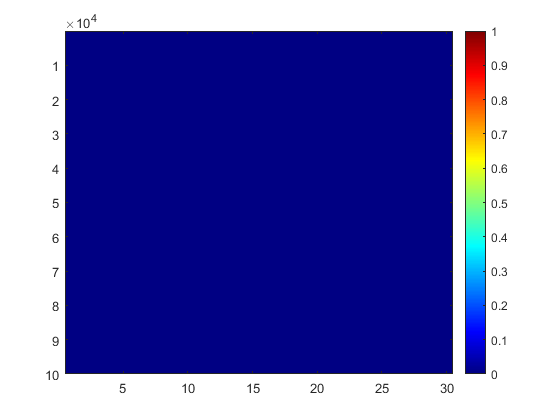

% Time Evolution

for i=1:Nx
        for j=1:Ny
            
            ip=i+1;
            im=i-1;
            
            jp=j+1;
            jm=j-1;
            
            if im==0
                im=1;
            end
            
            if ip==Nx+1
                ip=Nx;
            end
            
            if jm==0
                jm=1;
            end
            
            if jp==Ny+1
                jp=Ny;
            end
            
            % Time integration
            
            phi_old=phi(i,j);
            
            
            t1=(eps(i,jp)*d_eps(i,jp)*phi_dx(i,jp)-eps(i,jm)*d_eps(i,jm)*phi_dx(i,jm))/2/dy;
            
            t2=(eps(ip,j)*d_eps(ip,j)*phi_dy(ip,j)-eps(im,j)*d_eps(im,j)*phi_dy(im,j))/2/dx;
            
            g=phi_old^2*(1-phi_old)^2;
            
            g_dash=2*phi_old*(1-phi_old)^2-2*phi_old^2*(1-phi_old);
            
            random = -1 + (2)*rand(1,1);
            noise=16*alfa*random*phi_old^2*(1-phi_old)^2;
            
            t3=w*g_dash+30*g*H/Tm*(T(i,j)-Tm);
            
            phi(i,j)=phi(i,j)+(dt*M)*(t1-t2+eps(i,j)^2*lap_phi(i,j)-t3+noise);
                                        
            
            T(i,j)=T(i,j)+dt*D*lap_T(i,j)+H/Cp*30*g*(phi(i,j)-phi_old);
            
        end
end
n=n+1;

%%%%%%%%%%%% For dendrite tip speed uncomment this %%%%%%%%%%%
% phi_norm = zeros(size(phi));
% phi_norm(phi<0.5) = 0;
% phi_norm(phi>=0.5) = 1;
% colmin = zeros(Ny,1);
% for i=1:Ny
%     minred = find(phi_norm(:,i)==1, 1);
%     if isempty(minred)
%         colmin(i)=Nx;
%     else
%         colmin(i)=minred;
%     end
% end
% [gy(iter),gx(iter)] = min(colmin);
% end
% imagesc(phi)
% colormap("jet")
% colorbar


%%%%%%%%%%% For % of solid phase uncomment this
% if mod(iter,1000)==0
%     p(:,:,iter/1000)=phi;
% end


end 

x=1:Nx;

Elapsed time is 2365.657498 seconds.


y=1:Ny;
[X,Y]=meshgrid(x,y);
Z=griddata(x,y,phi,X,Y);
imshow(Z,"Colormap",jet)
colorbar

x=1:Nx;
y=1:Ny;
[X,Y]=meshgrid(x,y);
Z=griddata(x,y,T,X,Y);
imshow(Z,"Colormap",jet)
colorbar

toc
